# LIF Model with Adaptation Current

## Cm*dV/dt = (El - V)/Rm + Gsra*(Ek - V) + Iapp

## dGsra/dt = -Gsra/tausra

## if V >= Vth, V = Vreset and Gsra = Gsra + deltaGsra



clear; clc;

% Simulation parameters
T = 1.5; % Total time to simulate (s)
dt = 0.0001; % Simulation time step (s)
time = 0:dt:T; % Time array

% Neuron parameters
El = -75e-3; % Leak reversal potential (V)
Vth = -50e-3; % Spike threshold (V)
Vreset = -80e-3; % Reset potential (V)
Rm = 100e6; % Membrane resistance (ohm)

Cm = 100e-12; % Membrane capacitance (F)
Ek = -80e-3; % Potassium reversal potential (V)
deltaGsra = 1e-9; % Spike rate adaptation conductance (S)
tausra = 200e-3; % Adaptation conductance time constant (s)

% Applied current
Iapp = zeros(size(time));
Iapp(time>=0.5 & time<=1.0) = 500e-12; % 500 pA between 0.5 s and 1.0 s

% Initial conditions
V = El; % Set initial membrane potential to leak reversal potential
Gsra = 0; % Set initial spike rate adaptation conductance to 0

% Preallocate arrays
V_array = zeros(size(time));
Gsra_array = zeros(size(time));

## Firing Simulation

% Simulation loop
for i = 1:length(time)

    % Update adaptation conductance
    dGsra = -Gsra/tausra;
    Gsra = Gsra + dGsra*dt;
    
    % Update membrane potential
    dV = (El - V)/Rm + Gsra*(Ek - V) + Iapp(i);
    V = V + dV*dt/Cm;
    
    % Check for spike
    if V >= Vth
    V = Vreset;
    Gsra = Gsra + deltaGsra;
    end
    % Save variables into arrays
    V_array(i) = V;
    Gsra_array(i) = Gsra;
end


## Plot Results

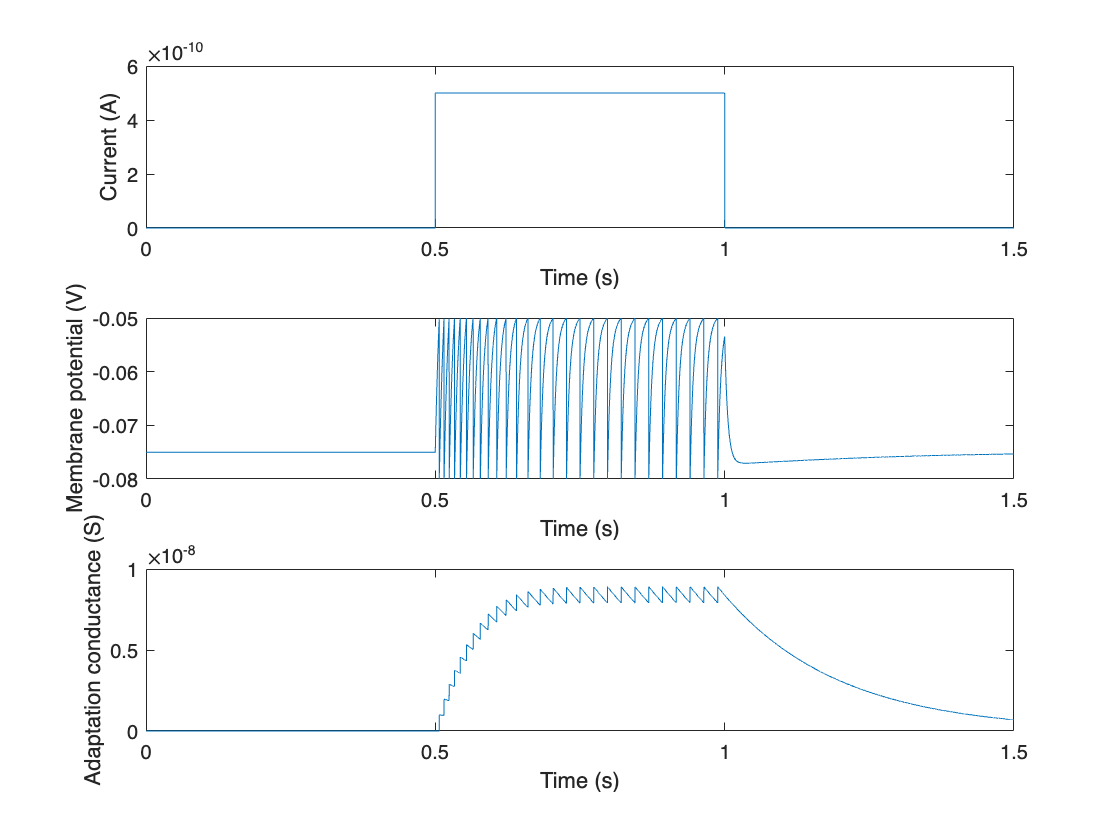

figure;

% Current
subplot(3,1,1);
plot(time, Iapp);
xlabel('Time (s)');
ylabel('Current (A)');

% Membrane potential
subplot(3,1,2);
plot(time, V_array);
xlabel('Time (s)');
ylabel('Membrane potential (V)');

% Adaptation conductance
subplot(3,1,3);
plot(time, Gsra_array);
xlabel('Time (s)');
ylabel('Adaptation conductance (S)');